clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions and load the files
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % We will load the 10th file in the sorted list, just like your draft
    file_to_load = names_sorted{10}; 
    fprintf('Loading %s for condition: %s\n', file_to_load, condition);
    
    EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
    if isempty(fs), fs = EEG.srate; end
    
    % Rebuild time vector (assuming 3.5s epochs as in original draft)
    time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 

    % Crop to 0.50 - 1120 msec
    valid_time_idx = time_ms_eeg >= 1.000 & time_ms_eeg <= 1.620; 
    time_cropped = time_ms_eeg(valid_time_idx);

    % Set excel file path for P2 and P3 conditions if needed
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
    else
        excel_file_path = '';
    end

    if ismember(condition, {'BLA', 'BLT', 'P1'})
        % Isolate the epochs with Auditory onset using odd number indexes
        epoch_trials = 1:2:EEG.trials;
        data_all_conds.(condition) = EEG.data(:, :, epoch_trials);

    elseif strcmp(condition, 'P2')
        % P2 has epochs preceding 500ms and 2000ms tactile events.
        % Indexes are provided in the Google Sheets file.
        epoch_trials_p2 = 1:2:EEG.trials;     
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
        data_all_conds.(condition) = EEG.data(:, :, epoch_trials_p2);
        data_all_conds.P2_500 = EEG.data(:, :, epoch_trials_p2_500ms);
        data_all_conds.P2_2000 = EEG.data(:, :, epoch_trials_p2_2000ms);
        % TODO: import the data for P2_500 and P2_2000 separately.
    elseif strcmp(condition, 'P3')
        % P3 has epochs preceding 500ms and missing tactile events.
        % Indexes are provided in the Google Sheets file.
        epoch_trials_p3 = 1:2:EEG.trials;
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
        data_all_conds.(condition) = EEG.data(:, :, epoch_trials_p3);
        data_all_conds.P3_500 = EEG.data(:, :, epoch_trials_p3_500ms);
        data_all_conds.P3_missing = EEG.data(:, :, epoch_trials_p3_missing);
    end
    
end

Loading binepochs filtered ICArej BLAAvgBOS5.set for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej BLTAvgBOS5.set for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P1AvgBOS5.set for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P2AvgBOS5.set for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading binepochs filtered ICArej P3AvgBOS5.set for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

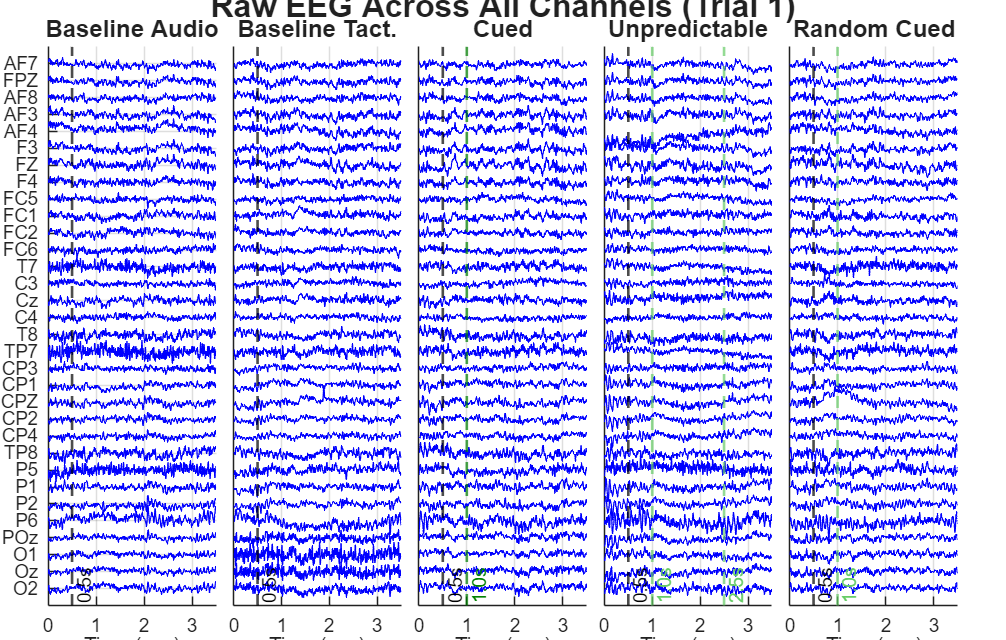

%% Visualizing All Channels Across Time (Subplots per Condition)
target_trial = 1; % Define which trial you want to inspect

% Safely extract channel labels for the Y-axis
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT, 1))')); 
end

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;
num_conds = length(conditions); 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG Across All Channels (Trial %d)', target_trial), 'FontSize', 24, 'FontWeight', 'bold');

% Offset: Use 30 for raw EEG microvolts, or reduce to 5 if using scaled/z-scored data
offset = 30; 
tick_positions = (num_channels_plot - display_channels) * offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % Extract [Channels x Time] for the specific target trial
    data_to_plot = data_all_conds.(cond_name)(:, :, target_trial);
    
    nexttile;
    hold on
    
    % 1. Plot the Channels
    for ch = 1:num_channels_plot
        % Stack channels vertically and strictly use blue ('b')
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    
    % Condition-specific event lines
    if strcmp(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    % (Ensure your time_cropped vector goes up to at least 2.5s to see the P2 line!)
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    
    xlabel('Time (sec)'); 
    
    % Only show Y-axis labels on the very first (leftmost) plot
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Baseline Audio';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Baseline Tact.';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    grid on;
end

## 1.3 Calculating the trail averaged signal per condition

disp('Calculating trial averages...');

Calculating trial averages...


cond_names = fieldnames(data_all_conds);
data_avg = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    % Average across the 3rd dimension (trials), ignoring NaNs if any exist
    data_avg.(c_name) = mean(data_all_conds.(c_name), 3, 'omitnan');
end


## Visualizing Trial-Averaged EEG Across Time (Subplots per Condition)

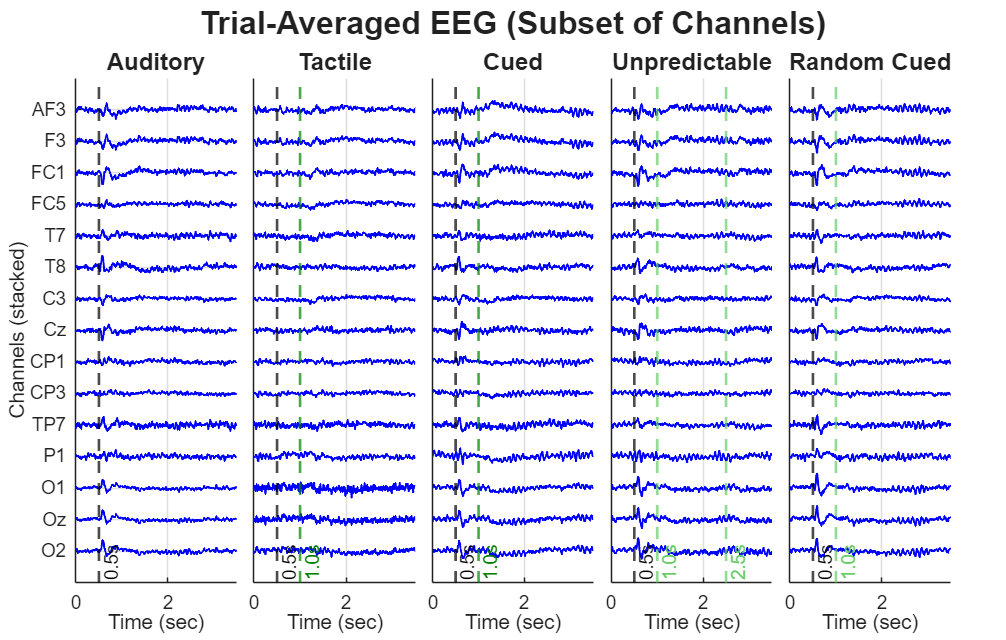

%% Visualizing Specific Channels Trial-Averaged Across Time

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace (assumes 1-32 string array)
    all_channels_str = cellstr(num2str((1:size(data_all_conds.BLT, 1))')); 
end

% 2. Find the indices of the requested channels within the full 32-channel list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);

% Safety check: remove any channels from the list that weren't found in your dataset (index 0)
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
display_channels = 1:1:num_channels_plot;
num_conds = length(conditions); 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Trial-Averaged EEG (Subset of Channels)', 'FontSize', 24, 'FontWeight', 'bold');

% Offset: adjust this (e.g., 10 to 30) based on how squished the averaged traces look
offset = 15; 
tick_positions = (num_channels_plot - display_channels) * offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % --- UPDATED DATA EXTRACTION ---
    % Average across the 3rd dimension (trials), but ONLY for the chan_idx rows!
    data_to_plot = mean(data_all_conds.(cond_name)(chan_idx, :, :), 3, 'omitnan');
    
    nexttile;
    hold on
    
    % 1. Plot the Sub-selected Channels
    for ch = 1:num_channels_plot
        % Stack channels vertically and strictly use blue ('b')
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.5);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    
    % Condition-specific event lines
    if ismember(cond_name, { 'BLT', 'P1'})
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    
    xlabel('Time (sec)'); 
    
    % Only show Y-axis labels on the very first (leftmost) plot
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); % Remove ticks for subsequent plots to maximize data visibility
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    grid on;
end

## 2.0 PCA per condition

%% 2.0 PCA per condition
% Mapping: ch x time -> comp x time
disp('Performing PCA per condition...');

Performing PCA per condition...


pca_results = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    X = data_avg.(c_name); % Size: [num_ch x time]
    
    % Mean center the data across time for PCA
    X_centered = X - mean(X, 2);
    
    % Perform PCA. MATLAB's pca() function expects [observations x variables].
    % We want components from channels, so we treat time points as observations 
    % and channels as variables, meaning we transpose X_centered.
    [coeff, score, latent, tsquared, explained] = pca(X_centered');
    
    % coeff is [ch x comp] (Spatial filters)
    % score is [time x comp] (Component time courses)
    
    pca_results.(c_name).coeff = coeff;
    pca_results.(c_name).comp_time = score'; % Transpose to match your desired [comp x time]
    pca_results.(c_name).explained = explained;
end

intrisic_dim = struct();

% Create the master figure for the tiled layout
figure('Position', [50 50 1600 1200]); 
tiledlayout(5, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

for i = 1:length(cond_names)
    c_name = cond_names{i};
    X = data_avg.(c_name); % Size: [num_ch x time]
    
    % The data's rank for the condition
    intrisic_dim.(c_name).rank = rank(X);

    % Marchenko–Pastur threshold (Added real() to prevent complex warnings)
    eig_vals = real(eig(cov(X'))); 
    [N, T] = size(X);
    Q = T / N;
    sigma2 = mean(eig_vals);           
    lambda_max = sigma2 * (1 + sqrt(1/Q))^2;
    
    % Find number of components above the MP threshold
    num_sig_components = sum(eig_vals > lambda_max);
    intrisic_dim.(c_name).num_sig_components = num_sig_components;

    fprintf('\n[%s] Marchenko–Pastur suggests keeping %d PCs\n', c_name, num_sig_components);
    
    % Move to the next tile in the 5x2 grid
    nexttile;
    
    % Call the updated function, passing the condition name for the title
    [num_factors, map_values] = velicer_map(X', c_name);
    
    intrisic_dim.(c_name).num_factors = num_factors;
end


[BLA] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 9 factors.



[BLT] Marchenko–Pastur suggests keeping 4 PCs


Velicer's MAP Test recommends retaining 8 factors.



[P1] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.



[P2] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 6 factors.



[P2_500] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.



[P2_2000] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 7 factors.



[P3] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 9 factors.



[P3_500] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 9 factors.



[P3_missing] Marchenko–Pastur suggests keeping 3 PCs


Velicer's MAP Test recommends retaining 10 factors.


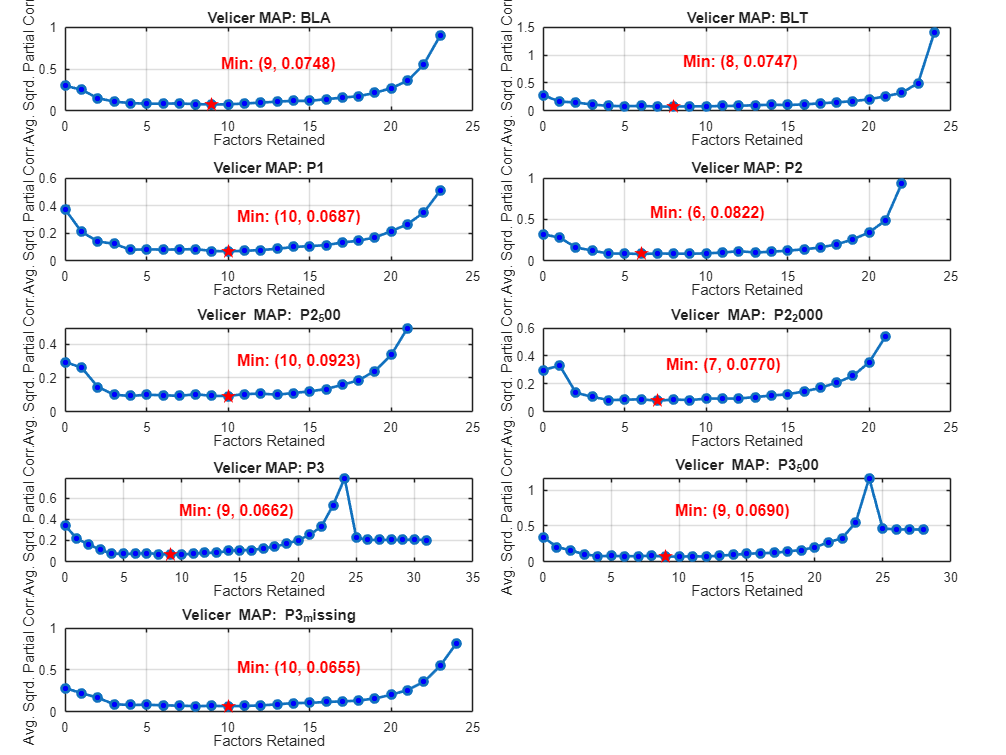

hold off;

function [num_factors, map_values] = velicer_map(data, cond_title)
% VELICER_MAP Determines the number of factors to retain using Velicer's MAP test.

    % 1. Compute the correlation matrix
    R = corrcoef(data);
    p = size(R, 1);
    
    % 2. Perform Eigenvalue Decomposition
    [eigvec, eigval_mat] = eig(R);
    
    % FIX: Wrap in real() to drop floating-point imaginary artifacts
    eigval = real(diag(eigval_mat));
    
    % Sort eigenvalues and eigenvectors in descending order
    [eigval, idx] = sort(eigval, 'descend');
    eigvec = real(eigvec(:, idx)); 
    
    % Initialize array to store the MAP values
    map_values = zeros(1, p);
    
    % 3. Step 0: Calculate average squared correlation (no factors partialled out)
    R_off_diag = R - eye(p);
    map_values(1) = sum(R_off_diag(:).^2) / (p * (p - 1));
    
    % 4. Loop to partial out 1 to p-1 components
    for m = 1:(p-1)
        A = eigvec(:, 1:m) * diag(sqrt(eigval(1:m)));
        part_cov = R - (A * A');
        
        d = diag(part_cov);
        inv_sqrt_d = diag(1 ./ sqrt(d));
        R_partial = inv_sqrt_d * part_cov * inv_sqrt_d;
        
        R_partial_off = R_partial - eye(p);
        map_values(m+1) = sum(R_partial_off(:).^2) / (p * (p - 1));
    end
    
    % 5. Find the minimum MAP value
    [min_val, min_idx] = min(map_values);
    num_factors = min_idx - 1;
    
    % 6. Plotting (Modified to use current active tile instead of a new figure)
    
    plot(0:(p-1), map_values, '-o', 'LineWidth', 2, 'MarkerFaceColor', 'b');
    hold on;
    % Highlight minimum
    plot(num_factors, map_values(min_idx), 'rp', 'MarkerSize', 10, 'MarkerFaceColor', 'r'); 
    
    coordinate_text = sprintf('  Min: (%d, %.4f)', num_factors, min_val);
    
    % Adjusted Y-coordinate and font sizes to fit nicely inside the subplots
    text(num_factors, max(map_values)*0.5, coordinate_text, ...
        'VerticalAlignment', 'bottom', ...
        'HorizontalAlignment', 'left', ...
        'FontSize', 12, ...
        'FontWeight', 'bold', ...
        'Color', 'r');
        
    xlabel('Factors Retained', 'FontSize', 10);
    ylabel('Avg. Sqrd. Partial Corr.', 'FontSize', 10);
    
    % Dynamic Title
    if nargin > 1
        title(sprintf('Velicer MAP: %s', char(cond_title)), 'FontSize', 14);
    else
        title('Velicer''s MAP Test', 'FontSize', 14);
    end
    
    set(gca,'FontSize', 10);
    grid on;
    hold off;
    
    % Output the result to the console
    fprintf('Velicer''s MAP Test recommends retaining %d factors.\n', num_factors);
end

## Visualizing Top 4 Principal Components Across Time (Subplots per Condition)

disp('Plotting PCA Component Time-Courses...');

Plotting PCA Component Time-Courses...


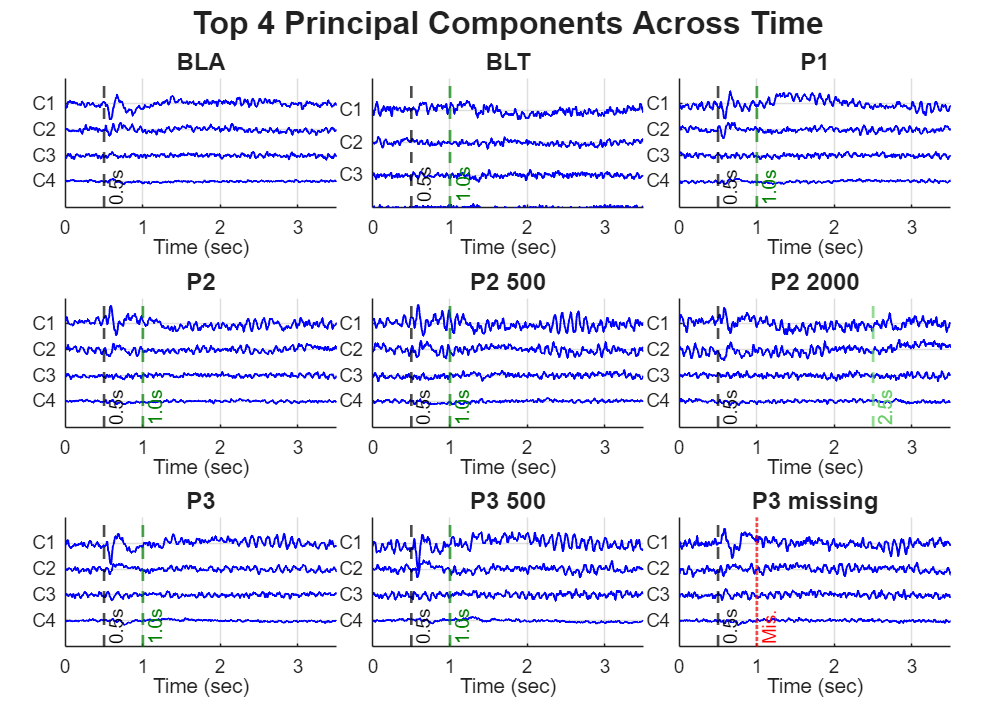


num_comps_plot = 4; % We want to plot the top 5 components
display_comps = 1:1:num_comps_plot;

% Extract condition names (including the split ones like P2_500, P2_2000)
all_cond_names = fieldnames(pca_results);
num_all_conds = length(all_cond_names); 

% Create a wide figure to comfortably fit side-by-side plots
figure('Position',[50 50 2000 1400], 'Name', 'PCA Top 5 Components');
t = tiledlayout(3, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Top 4 Principal Components Across Time', 'FontSize', 24, 'FontWeight', 'bold');

% Offset: adjust this to pack the component traces tighter or looser vertically
% Components usually have smaller amplitude than raw EEG, so an offset of 5 to 10 is usually good.
comp_offset = 30; 
tick_positions = (num_comps_plot - display_comps) * comp_offset;

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all available conditions
for c = 1:num_all_conds
    cond_name = all_cond_names{c};
    
    % Extract [Comp x Time] data
    % pca_results.(cond_name).comp_time has size [TotalComps x Time]
    comp_to_plot = pca_results.(cond_name).comp_time(1:num_comps_plot, :);
    
    nexttile;
    hold on
    
    % 1. Plot the Components
    for comp_idx = 1:num_comps_plot
        % Stack components vertically and use a distinct color (e.g., dark red)
        plot(time_ms_eeg, comp_to_plot(comp_idx, :) + (num_comps_plot - comp_idx)*comp_offset, 'b', 'LineWidth', 1.5);
    end
    
    % 2. Add Vertical Event Lines
    % All conditions get a dashed vertical line at time 0.5 sec (Audio Onset)
    xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    
    % Condition-specific tactile event lines
    if any(strcmp(cond_name, {'BLT', 'P1', 'P2', 'P2_500', 'P3', 'P3_500'}))
        % Expected tactile onset at 1.0s
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif contains(cond_name, 'P2_2000')
        % Delayed tactile onset at 2.5s
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        
    elseif contains(cond_name, 'P3_missing')
        % Missing tactile - draw a red line to indicate where it SHOULD have been
        xline(1.0, 'r:', 'Mis.', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off
    
    % Fit the X-axis strictly to our cropped time window
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    
    % Set y-limits to frame the stacked traces perfectly
    ylim([-comp_offset, num_comps_plot*comp_offset]);
    
    xlabel('Time (sec)'); 
    % ylabel('Components (stacked)');
    yticks(flip(tick_positions));
    
    % Create string array like {'C1', 'C2', 'C3', 'C4', 'C5'}
    yticklabels(flip(arrayfun(@(x) sprintf('C%d', x), 1:num_comps_plot, 'UniformOutput', false)));
    set(gca,'FontSize',14);
    
    % Format the title cleanly (removes underscores so MATLAB doesn't make subscripts)
    plot_title = strrep(cond_name, '_', ' ');
    title(plot_title, 'FontSize', 18);
    grid on;
end

%% Visualizing Top 3 Principal Components Overlaid (3 Subplots Total)
disp('Plotting Top 3 PCA Components Overlaid...');

Plotting Top 3 PCA Components Overlaid...


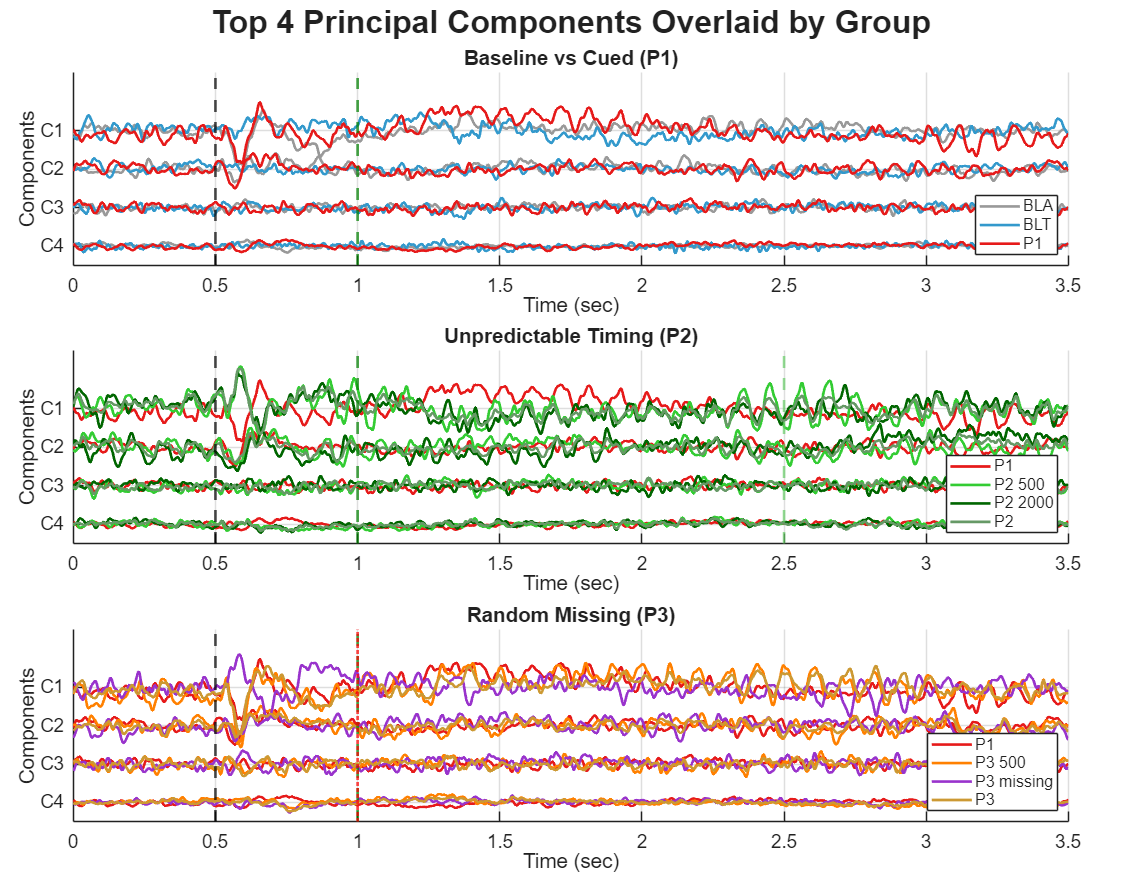


num_comps_plot = 4; % Top 3 components
display_comps = 1:1:num_comps_plot;

% Define the 3 groups for the 3 subplots
plot_groups = {
    {'BLA', 'BLT', 'P1'},                      % Subplot 1
    {'P1', 'P2_500', 'P2_2000', 'P2'},         % Subplot 2 'P2_500', 'P2_2000',
    {'P1', 'P3_500', 'P3_missing', 'P3'}       % Subplot 3 'P3_500', 'P3_missing',
};

% Set up consistent colors for conditions so they match across subplots.
% You can adjust these RGB arrays to fit your preferred aesthetic!
color_map = struct(...
    'BLA', [0.6 0.6 0.6], ...       % Gray
    'BLT', [0.2 0.6 0.8], ...       % Light Blue
    'P1',  [0.9 0.1 0.1], ...       % Red
    'P2_500', [0.2 0.8 0.2], ...    % Bright Green
    'P2_2000', [0.0 0.4 0.0], ...   % Dark Green
    'P2', [0.4 0.6 0.4], ...        % Olive Green
    'P3_500', [1.0 0.5 0.0], ...    % Orange
    'P3_missing', [0.6 0.2 0.8], ...% Purple
    'P3', [0.8 0.6 0.2] ...         % Gold
);

% Create a wide figure for 3 side-by-side subplots
figure('Position',[50 50 1800 1400], 'Name', 'Overlaid PCA Components');
t = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Top 4 Principal Components Overlaid by Group', 'FontSize', 24, 'FontWeight', 'bold');

% Generous offset so the overlaid variations don't bleed into adjacent components
comp_offset = 20; 
tick_positions = (num_comps_plot - display_comps) * comp_offset;
y_tick_labels = flip(arrayfun(@(x) sprintf('C%d', x), 1:num_comps_plot, 'UniformOutput', false));

% Loop through the 3 subplots
for g = 1:length(plot_groups)
    conds_in_group = plot_groups{g};
    
    nexttile;
    hold on;
    
    % Pre-allocate an array to store plot handles for the legend
    h_lines = gobjects(1, length(conds_in_group)); 
    
    for c = 1:length(conds_in_group)
        cond_name = conds_in_group{c};
        
        % Grab color from our map, fallback to random if missing
        if isfield(color_map, cond_name)
            clr = color_map.(cond_name);
        else
            clr = rand(1,3); 
        end
        
        % Extract [Comp x Time] data
        comp_to_plot = pca_results.(cond_name).comp_time(1:num_comps_plot, :);
        
        % Plot the stacked components for this specific condition
        for comp_idx = 1:num_comps_plot
            y_offset = (num_comps_plot - comp_idx) * comp_offset;
            
            p = plot(time_ms_eeg, comp_to_plot(comp_idx, :) + y_offset, ...
                'Color', clr, 'LineWidth', 2.0);
            
            % Save the plot handle of the very first component to build the legend
            if comp_idx == 1
                h_lines(c) = p;
            end
        end
    end
    
    % Add Vertical Event Lines customized for each subplot
    xline(0.5, 'k--', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom'); % Audio
    
    if g == 1
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        title('Baseline vs Cued (P1)', 'FontSize', 18);
        
    elseif g == 2
        xline(1.0, '--',  'Color', [0 0.5 0], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        title('Unpredictable Timing (P2)', 'FontSize', 18);
        
    elseif g == 3
        xline(1.0, '--',  'Color', [0 0.5 0], 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(1.0, 'r:', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'top');
        title('Random Missing (P3)', 'FontSize', 18);
    end
    
    hold off;
    
    % Axis Limits and Labels
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    % xlim([0.5, 1.3]); 
    ylim([-comp_offset*0.5, num_comps_plot*comp_offset + comp_offset*0.5]);
    
    xlabel('Time (sec)');
    
    ylabel('Components');
    yticks(flip(tick_positions));
    yticklabels(y_tick_labels);
    
    set(gca,'FontSize',14);
    grid on;
    
    % Generate a clean legend for exactly the conditions in this subplot
    clean_names = strrep(conds_in_group, '_', ' '); % Removes underscores for MATLAB rendering
    legend(h_lines, clean_names, 'Location', 'southeast', 'FontSize', 12);
end

## 2.1 Cosine between conditions for Auditory ERP for the three time periods: 0-60 ms, 60-200 ms, 200-500 msec after stimulus

% Cosine similarity between BLA and target conditions
disp('Calculating Cosine Similarities...');

Calculating Cosine Similarities...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-tactile stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% The conditions to compare against BLT
compare_conds = {'P1', 'P2_500', 'P2_2000', 'P3_500', 'P3_missing'};
ref_cond = 'BLA';

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage for similarities: struct -> window -> matrix
cos_sim_results = struct();

for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    tgt_onset_ms = 500; % for all conditions at 0.5 sec
    
    % Reference onset is always 1000ms for BLT
    ref_onset_ms = 500; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets to avoid floating-point indexing mismatches
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for the specified window
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        % pdist2 with 'cosine' returns Cosine Distance (1 - cos(theta)).
        % We feed it [comp x time], so it treats rows (components) as observations
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert back to similarity [-1 to 1]
        
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix;
    end
end

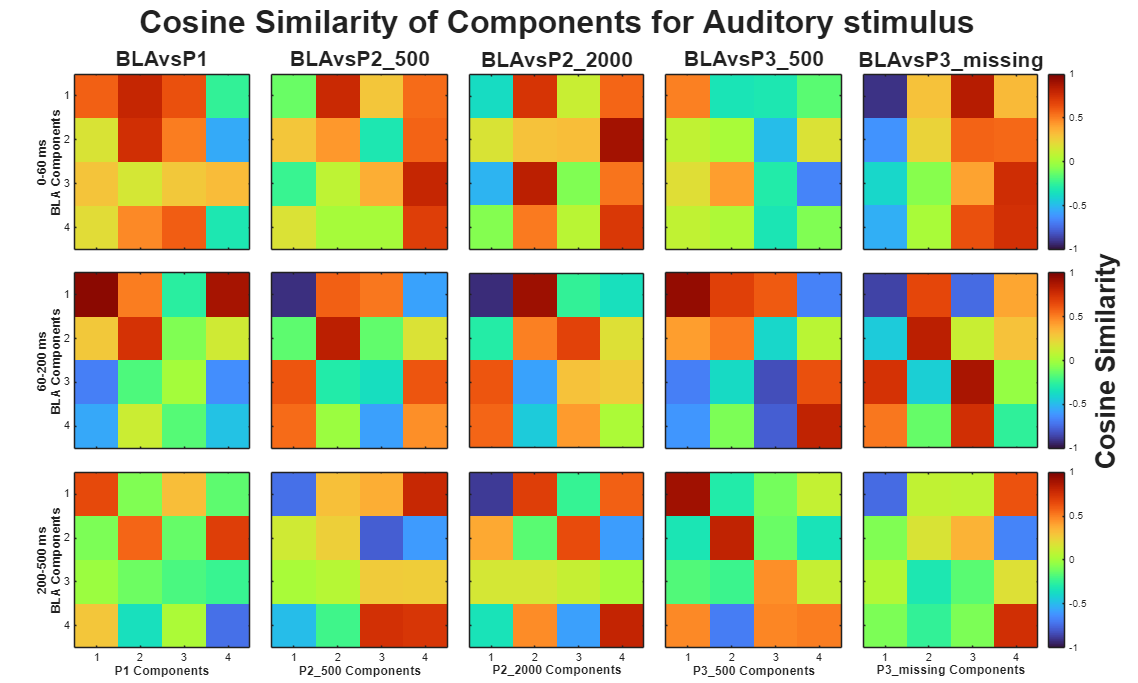

figure('Position', [100, 100, 2000, 1200], 'Name', 'PCA Cosine Similarity');

% 3 Rows (time windows) x 5 Columns (conditions)
t = tiledlayout(length(time_windows_relative), length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

% SWAP LOOPS: Outer loop for rows (windows), inner loop for columns (conditions)
for w = 1:length(time_windows_relative)
    for c = 1:length(compare_conds)
        tgt_cond = compare_conds{c};
        
        nexttile;
        
        % Get the similarity matrix calculated in 2.1
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        % Plot heatmap
        imagesc(sim_mat);
        colormap('turbo'); % 'turbo' or 'parula'
        caxis([-1 1]);     % Cosine similarity ranges from -1 to 1
        
        % Formatting
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % 1. Only show X-axis labels on the BOTTOM row (last time window)
        if w == length(time_windows_relative)
            xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            xticklabels({}); % Hide ticks for inner tiles
        end
        
        % 2. Only show Y-axis labels on the LEFTMOST column (first condition)
        if c == 1
            % Combine the window name and the reference condition into one clean Y-label
            ylabel(sprintf('%s\n%s Components', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({}); % Hide ticks for inner tiles
        end
        
        % 3. Title strings (Only put titles on the TOP row to avoid cluttering the grid)
        if w == 1
            title(sprintf('%svs%s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
        end
        
        % 4. Add colorbar only to the RIGHTMOST column to save space
        if c == length(compare_conds)
            cb = colorbar;
            if w == round(length(time_windows_relative)/2) % Only label the middle colorbar for symmetry
                cb.Label.String = 'Cosine Similarity';
                cb.Label.FontSize = 20;
                cb.Label.FontWeight = 'bold';
            end
        end
        
    end
end

title(t, 'Cosine Similarity of Components for Auditory stimulus', 'FontSize', 24, 'FontWeight', 'bold');

%% Condition comparison vs. P1
% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% --- NEW CONFIGURATION ---
ref_cond = 'P1'; % P1 is now the reference

% Group the target conditions exactly as requested
group1 = {'BLT', 'BLA'};
group2 = {'P2_500', 'P2_2000', 'P2'};
group3 = {'P3_500', 'P3_missing', 'P3'};

% Combine them into one list for the calculation loop
all_targets = [group1, group2, group3];

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage
cos_sim_results = struct();

for c = 1:length(all_targets)
    tgt_cond = all_targets{c};
    
    % Define the absolute onset time for the TARGET condition
    tgt_onset_ms = 500;
    % Reference onset is always 1000ms for P1
    ref_onset_ms = 500; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert distance to similarity [-1 to 1]
        
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix;
    end
end


%% 2.2 Heatmaps for cosine similarity (Grouped into 3 Figures)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


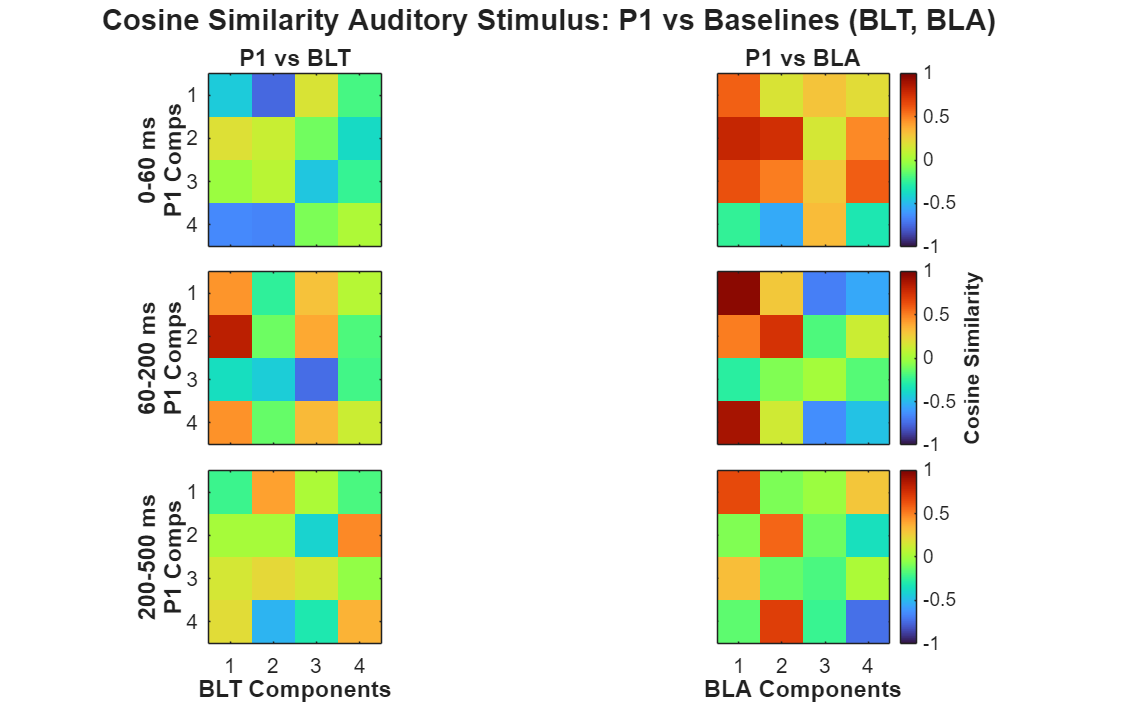

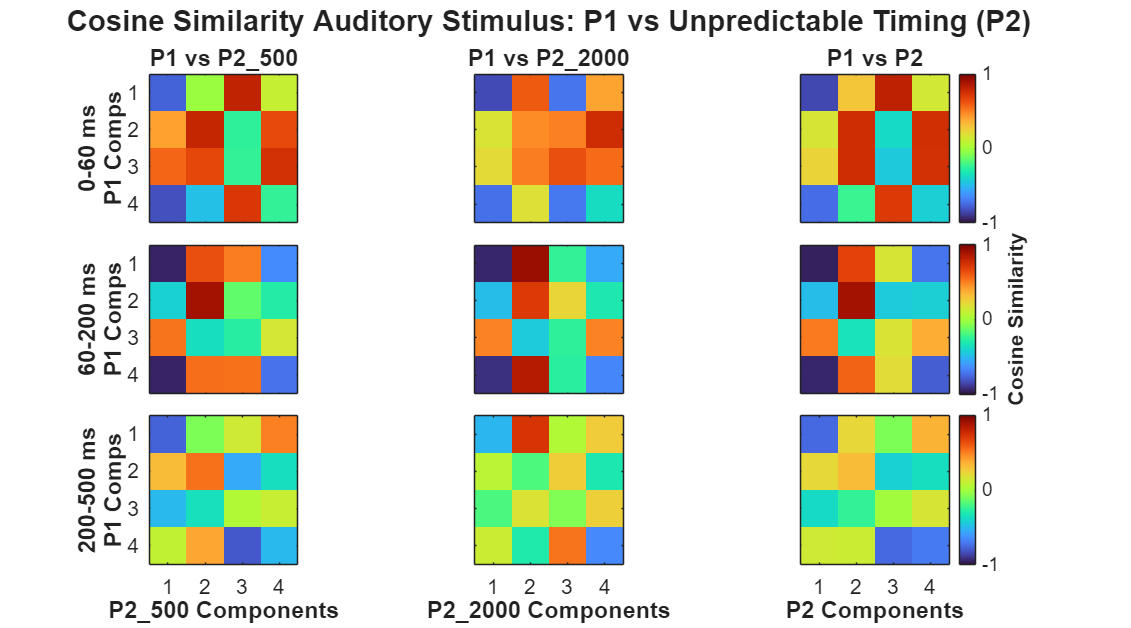

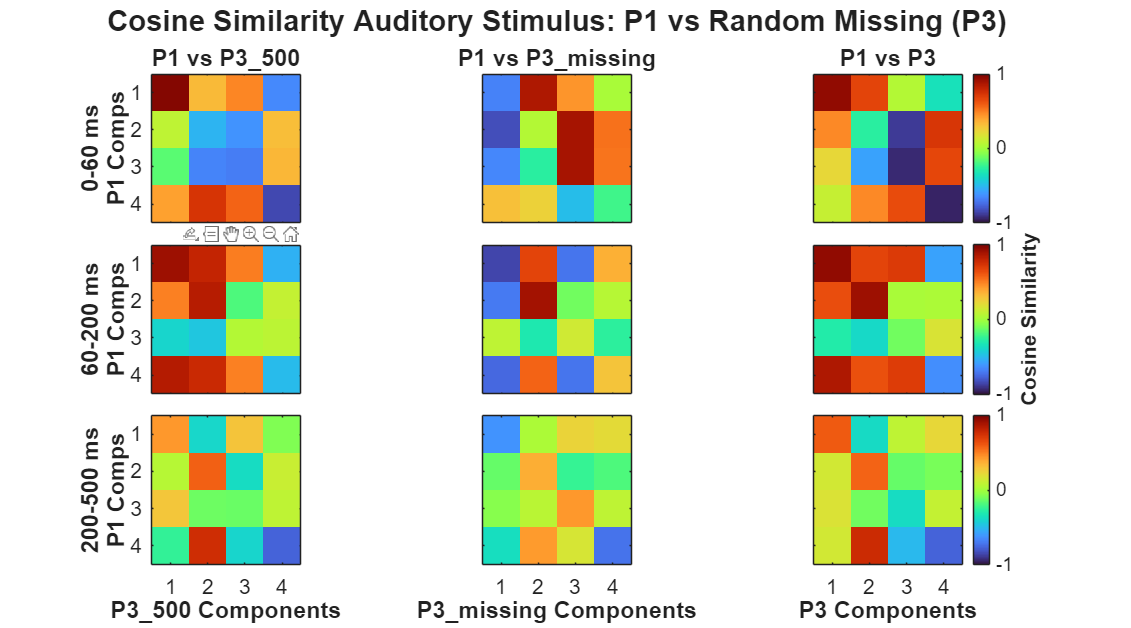


% Organize the groups and titles for the figures
plot_groups = {group1, group2, group3};
group_titles = {
    'Cosine Similarity Auditory Stimulus: P1 vs Baselines (BLT, BLA)', 
    'Cosine Similarity Auditory Stimulus: P1 vs Unpredictable Timing (P2)', 
    'Cosine Similarity Auditory Stimulus: P1 vs Random Missing (P3)'
};

% Generate a separate figure for each group
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    
    % Offset figure positions slightly so they don't completely overlap on your screen
    fig_pos = [50 + (g*30), 50 + (g*30), 1200 + (length(current_group)*200), 1000];
    figure('Position', fig_pos, 'Name', sprintf('PCA Cosine Sim - Group %d', g));
    
    % Layout: Rows = Time Windows, Columns = Target Conditions
    t = tiledlayout(length(time_windows_relative), length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    
    for w = 1:length(time_windows_relative)
        for c = 1:length(current_group)
            tgt_cond = current_group{c};
            
            nexttile;
            
            % Get the similarity matrix
            sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
            
            % Plot heatmap
            imagesc(sim_mat);
            colormap('turbo'); 
            caxis([-1 1]);     
            
            % Formatting
            axis square;
            xticks(1:num_comps);
            yticks(1:num_comps);
            
            % X-axis labels strictly on the bottom row
            if w == length(time_windows_relative)
                xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                xticklabels({});
            end
            
            % Y-axis labels strictly on the leftmost column
            if c == 1
                ylabel(sprintf('%s\n%s Comps', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            % Titles strictly on the top row
            if w == 1
                title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
            end
            
            % Colorbar only on the far right column
            if c == length(current_group)
                cb = colorbar;
                if w == round(length(time_windows_relative)/2) % Label the middle one for symmetry
                    cb.Label.String = 'Cosine Similarity';
                    cb.Label.FontWeight = 'bold';
                    cb.Label.FontSize = 16;
                end
            end
            set(gca,'FontSize',16);
        end
    end
    
    % Add the overarching title for the specific group
    title(t, group_titles{g}, 'FontSize', 22, 'FontWeight', 'bold');
end

## 2.1 Cosine similarity between BLT components and (P1,P2_500,P2_2000,P3_500,P3_missing)

%% 2.1 Cosine similarity between BLT and target conditions
disp('Calculating Cosine Similarities...');

Calculating Cosine Similarities...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-tactile stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% The conditions to compare against BLT
compare_conds = {'P1', 'P2_500', 'P2_2000', 'P3_500', 'P3_missing'};
ref_cond = 'BLT';

% We will compare the top 10 principal components
num_comps = 4; 

% Pre-allocate storage for similarities: struct -> window -> matrix
cos_sim_results = struct();

for c = 1:length(compare_conds)
    tgt_cond = compare_conds{c};
    
    % Define the absolute onset time of the tactile stimulus for the TARGET condition
    if strcmp(tgt_cond, 'P2_2000')
        tgt_onset_ms = 2500; 
    else
        tgt_onset_ms = 1000; % 1.0s for BLT, P1, P2_500, P3_500, and P3_missing expected
    end
    
    % Reference onset is always 1000ms for BLT
    ref_onset_ms = 1000; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets to avoid floating-point indexing mismatches
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data for the specified window
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        % pdist2 with 'cosine' returns Cosine Distance (1 - cos(theta)).
        % We feed it [comp x time], so it treats rows (components) as observations
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert back to similarity [-1 to 1]
        
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix;
    end
end

## 2.2 Heatmaps for cosine similarity for the three time periods: 0-60 ms, 60-200 ms, 200-300 msec

disp('Plotting Heatmaps...');

Plotting Heatmaps...


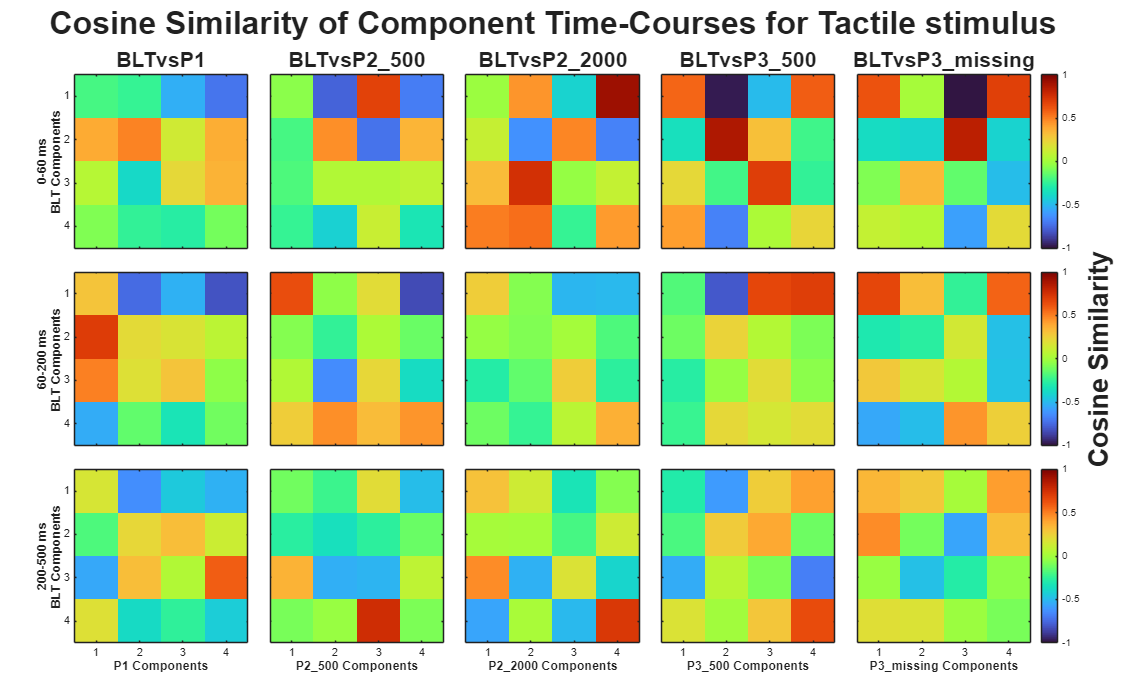


figure('Position', [100, 100, 2000, 1200], 'Name', 'PCA Cosine Similarity');

% 3 Rows (time windows) x 5 Columns (conditions)
t = tiledlayout(length(time_windows_relative), length(compare_conds), 'TileSpacing', 'compact', 'Padding', 'compact');

% SWAP LOOPS: Outer loop for rows (windows), inner loop for columns (conditions)
for w = 1:length(time_windows_relative)
    for c = 1:length(compare_conds)
        tgt_cond = compare_conds{c};
        
        nexttile;
        
        % Get the similarity matrix calculated in 2.1
        sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
        
        % Plot heatmap
        imagesc(sim_mat);
        colormap('turbo'); % 'turbo' or 'parula'
        caxis([-1 1]);     % Cosine similarity ranges from -1 to 1
        
        % Formatting
        axis square;
        xticks(1:num_comps);
        yticks(1:num_comps);
        
        % 1. Only show X-axis labels on the BOTTOM row (last time window)
        if w == length(time_windows_relative)
            xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            xticklabels({}); % Hide ticks for inner tiles
        end
        
        % 2. Only show Y-axis labels on the LEFTMOST column (first condition)
        if c == 1
            % Combine the window name and the reference condition into one clean Y-label
            ylabel(sprintf('%s\n%s Components', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
        else
            yticklabels({}); % Hide ticks for inner tiles
        end
        
        % 3. Title strings (Only put titles on the TOP row to avoid cluttering the grid)
        if w == 1
            title(sprintf('%svs%s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
        end
        
        % 4. Add colorbar only to the RIGHTMOST column to save space
        if c == length(compare_conds)
            cb = colorbar;
            if w == round(length(time_windows_relative)/2) % Only label the middle colorbar for symmetry
                cb.Label.String = 'Cosine Similarity';
                cb.Label.FontSize = 20;
                cb.Label.FontWeight = 'bold';
            end
        end
        
    end
end

title(t, 'Cosine Similarity of Component Time-Courses for Tactile stimulus', 'FontSize', 24, 'FontWeight', 'bold');

%% 2.1 Cosine similarity between P1 and target conditions
disp('Calculating Cosine Similarities...');

Calculating Cosine Similarities...



% Define the time axis in milliseconds
time_ms = time_ms_eeg * 1000; 

% Define relative time windows (post-stimulus) in ms
time_windows_relative = {[0, 60], [60, 200], [200, 500]};
window_names = {'0-60 ms', '60-200 ms', '200-500 ms'};

% --- NEW CONFIGURATION ---
ref_cond = 'P1'; % P1 is now the reference

% Group the target conditions exactly as requested
group1 = {'BLT', 'BLA'};
group2 = {'P2_500', 'P2_2000', 'P2'};
group3 = {'P3_500', 'P3_missing', 'P3'};

% Combine them into one list for the calculation loop
all_targets = [group1, group2, group3];

% We will compare the top 10 principal components
num_comps = 3; 

% Pre-allocate storage
cos_sim_results = struct();

for c = 1:length(all_targets)
    tgt_cond = all_targets{c};
    
    % Define the absolute onset time for the TARGET condition
    if strcmp(tgt_cond, 'P2_2000')
        tgt_onset_ms = 2500; 
    else
        tgt_onset_ms = 1000; % 1.0s onset for P1, BLA, BLT, P2_500, P3_500, P3_missing, and the general P2/P3
    end
    
    % Reference onset is always 1000ms for P1
    ref_onset_ms = 1000; 
    
    for w = 1:length(time_windows_relative)
        win = time_windows_relative{w};
        
        % Convert ms windows into discrete sample offsets
        sample_offset_start = round(win(1) / 1000 * fs);
        sample_offset_end   = round(win(2) / 1000 * fs);
        
        % Find the exact center index for the onsets
        ref_idx_center = find(time_ms >= ref_onset_ms, 1);
        tgt_idx_center = find(time_ms >= tgt_onset_ms, 1);
        
        % Create the sample range for this window
        ref_idx_range = (ref_idx_center + sample_offset_start) : (ref_idx_center + sample_offset_end);
        tgt_idx_range = (tgt_idx_center + sample_offset_start) : (tgt_idx_center + sample_offset_end);
        
        % Extract the [comp x time] data
        comp_ref = pca_results.(ref_cond).comp_time(1:num_comps, ref_idx_range);
        comp_tgt = pca_results.(tgt_cond).comp_time(1:num_comps, tgt_idx_range);
        
        % Compute pairwise Cosine Similarity
        cos_dist = pdist2(comp_ref, comp_tgt, 'cosine');
        cos_sim_matrix = 1 - cos_dist; % Convert distance to similarity [-1 to 1]
        
        cos_sim_results.(tgt_cond).(sprintf('win_%d', w)) = cos_sim_matrix;
    end
end


%% 2.2 Heatmaps for cosine similarity (Grouped into 3 Figures)
disp('Plotting Heatmaps...');

Plotting Heatmaps...


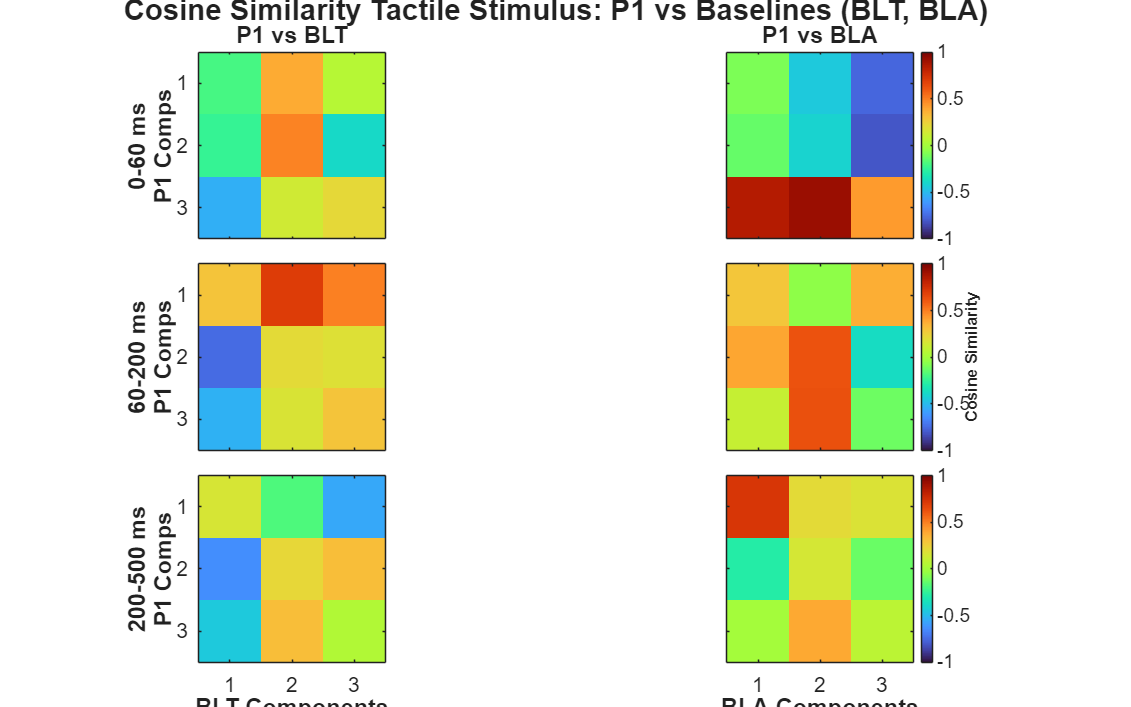


% Organize the groups and titles for the figures
plot_groups = {group1, group2, group3};
group_titles = {
    'Cosine Similarity Tactile Stimulus: P1 vs Baselines (BLT, BLA)', 
    'Cosine Similarity Tactile Stimulus: P1 vs Unpredictable Timing (P2)', 
    'Cosine Similarity Tactile Stimulus: P1 vs Random Missing (P3)'
};

% Generate a separate figure for each group
for g = 1:length(plot_groups)
    current_group = plot_groups{g};
    
    % Offset figure positions slightly so they don't completely overlap on your screen
    fig_pos = [50 + (g*30), 50 + (g*30), 1200 + (length(current_group)*200), 1000];
    figure('Position', fig_pos, 'Name', sprintf('PCA Cosine Sim - Group %d', g));
    
    % Layout: Rows = Time Windows, Columns = Target Conditions
    t = tiledlayout(length(time_windows_relative), length(current_group), 'TileSpacing', 'compact', 'Padding', 'compact');
    
    for w = 1:length(time_windows_relative)
        for c = 1:length(current_group)
            tgt_cond = current_group{c};
            
            nexttile;
            
            % Get the similarity matrix
            sim_mat = cos_sim_results.(tgt_cond).(sprintf('win_%d', w));
            
            % Plot heatmap
            imagesc(sim_mat);
            colormap('turbo'); 
            caxis([-1 1]);     
            
            % Formatting
            axis square;
            xticks(1:num_comps);
            yticks(1:num_comps);
            
            % X-axis labels strictly on the bottom row
            if w == length(time_windows_relative)
                xlabel(sprintf('%s Components', tgt_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                xticklabels({});
            end
            
            % Y-axis labels strictly on the leftmost column
            if c == 1
                ylabel(sprintf('%s\n%s Comps', window_names{w}, ref_cond), 'Interpreter', 'none', 'FontWeight', 'bold');
            else
                yticklabels({});
            end
            
            % Titles strictly on the top row
            if w == 1
                title(sprintf('%s vs %s', ref_cond, tgt_cond), 'Interpreter', 'none', 'FontSize', 16);
            end
            
            % Colorbar only on the far right column
            if c == length(current_group)
                cb = colorbar;
                if w == round(length(time_windows_relative)/2) % Label the middle one for symmetry
                    cb.Label.String = 'Cosine Similarity';
                    cb.Label.FontWeight = 'bold';
                    cb.Label.FontSize = 12;
                end
            end
            set(gca,'FontSize',16);
        end
    end
    
    % Add the overarching title for the specific group
    title(t, group_titles{g}, 'FontSize', 22, 'FontWeight', 'bold');
end